复化梯形

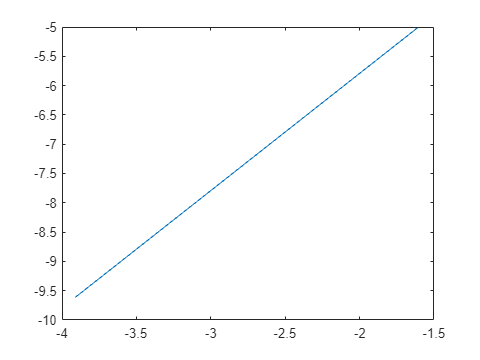

clc
clear
T=zeros(1,10);
for n=5:5:50
    o=0;
    h=1/n;
    x=0:h:1;
    for i=2:n
        o=o+4/(1+x(i)^2);
    end
    T(n/5)=h/2*(2+4+2*o);
end
delta1=zeros(1,10);
for i=1:10
    delta1(i)=log(abs(pi-T(i)));
end
x1=[-log(5),-log(10),-log(15),-log(20),-log(25),-log(30),-log(35),-log(40),-log(45),-log(50)];
plot(x1,delta1);

l=0.001;
z=0:l:1

z =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


c=0;
for i=2:1000
    c=c+4/(1+z(i)^2);
end
K=0.001/2*(2+4+2*c)-pi

K = -1.6667e-07

(delta1(10)-delta1(1))/(x1(10)-x1(1))

ans = 2.0000

复化Simpson

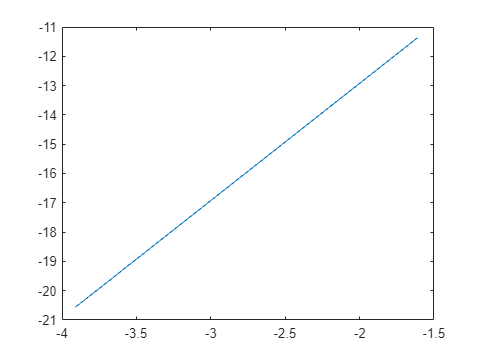

clc
clear
S=zeros(1,10);
for m=5:5:50
    p=0;
    q=0;
    g=1/m;
    y=0:g/2:1;
    for i=2:2:2*m
        p=p+4/(1+y(i).^2);
    end
    for i=3:2:2*m
        q=q+4/(1+y(i).^2);
    end
    S(m/5)=g/6*(2+4+2*q+4*p);
end
delta2=zeros(1,10);
for i=1:10
    delta2(i)=2*log(pi-S(i))/3;
end
x2=[-log(5),-log(10),-log(15),-log(20),-log(25),-log(30),-log(35),-log(40),-log(45),-log(50)];
plot(x2,delta2);

a=(delta2(7)-delta2(1))/(x2(7)-x2(1))

a = 3.9991

Romberg

clc
clear
a = 0;
b = 1;
e = 1e-15;
syms x;
f(x) = 4/(1+x.^2);
R=Romberg_Iteration(f,a,b,e)

R =     3.0000         0         0         0         0         0         0         0         0
    3.1000    3.1333         0         0         0         0         0         0         0
    3.1312    3.1416    3.1421         0         0         0         0         0         0
    3.1390    3.1416    3.1416    3.1416         0         0         0         0         0
    3.1409    3.1416    3.1416    3.1416    3.1416         0         0         0         0
    3.1414    3.1416    3.1416    3.1416    3.1416    3.1416         0         0         0
    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416         0         0
    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416         0
    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416


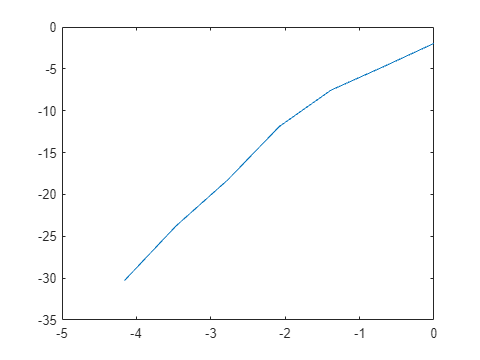

h=zeros(1,9);
delta3=zeros(1,9);
for i=1:9
    h(i)=log(1/2.^(i-1));
    delta3(i)=log(abs(R(i,i)-pi));
end
plot(h,delta3)

(delta3(7)-delta3(3))/(h(7)-h(3))

ans = 8.1957